heatmap for exposed surface

plot stlmsh

vertices = readtable('stl_vertices.csv');
faces = readtable('stl_faces.csv');

v_arr = [vertices.x, vertices.y, vertices.z];
f_arr = [faces.v1, faces.v2, faces.v3] + 1;

figure;
trisurf(f_arr, v_arr(:,1), v_arr(:,2), v_arr(:,3),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceAlpha',0.5)
lighting gouraud
camlight('left')
camlight('right')

hold on;

f

retractions = readtable('retraction_results\L1A2.csv')

retractions = 15×12 table
    Var1    expert    level    activity         x            y           z         dx       dy       dz       F      id
    ____    ______    _____    ________    ___________    ________    ________    _____    _____    _____    ____    __

      1       1         1         2         -0.0029658    0.060176    0.031888    -0.76    -0.52     0.39    6.29     4
     16       1         1         2         -0.0024905    0.061863    0.034173    -0.66    -0.73    -0.15    3.59    21
     31       0         1         2         0.00092358    0.065274    0.031773    -0.

r_x = retractions.x;
r_y = retractions.y;
r_z = retractions.z;
r_dx = retractions.dx;
r_dy = retractions.dy;
r_dz = retractions.dz;
r_f = retractions.F;
is_expert = retractions.expert;
r_id = retractions.id;
results = readtable('optimization_results/L1A2 SAD fine.csv')

results = 71×11 table
    Var1    retraction_ind       pos_x        pos_y       pos_z       dir_x       dir_y       dir_z      area_exposed    stress_induced    displacement
    ____    ______________    ___________    ________    ________    ________    ________    ________    ____________    ______________    ____________

     35          161            0.0045244    0.043049      0.0262    -0.17101    -0.96985     0.17365     1.6416e-05         6853.8          0.006049  
    103          169           0.00099874    0.045679    0.028988    -0.17101    -0.96985    -0.17365     1.5823e-05         7523.4         0.00594

results = sortrows(results,'area_exposed','descend')

results = 71×11 table
    Var1    retraction_ind       pos_x        pos_y       pos_z       dir_x       dir_y       dir_z      area_exposed    stress_induced    displacement
    ____    ______________    ___________    ________    ________    ________    ________    ________    ____________    ______________    ____________

    1810         625          -0.00010379    0.065615    0.036654    -0.92542    -0.33682     0.17365     2.2694e-05         22721          0.0096995  
    1935         667           0.00071589    0.066643    0.039213    -0.92542    -0.33682    -0.17365     2.2533e-05         22389          0.00920

x = results.pos_x;
y = results.pos_y;
z = results.pos_z;
dx = results.dir_x;
dy = results.dir_y;
dz = results.dir_z;
dissect_pos =[0.01075815	0.06802344	0.0359168]

dissect_pos =     0.0108    0.0680    0.0359






area = results.area_exposed;
area_norm = rescale(area,1,255);
stress = results.stress_induced;
stress_norm = rescale(stress, 1, 255);
disp = results.displacement;
disp_norm = rescale(disp, 1, 255);

score = disp_norm

score =   255.0000
  232.2267
  233.1378
  203.5905
  187.8680
  216.0120
  205.4800
  220.7589
  226.7738
  198.7833
  203.9139
  201.7095
  191.5611
  193.3167
  161.2871


score = rescale(sort(score(1:10),"descend"),1, 255)

score =   255.0000
  172.2823
  168.8351
  148.2038
  125.4458
  107.4854
   67.6366
   60.4874
   42.2990
    1.0000


score_len = rescale(score, 0.01, 0.05)

score_len =     0.0500
    0.0370
    0.0364
    0.0332
    0.0296
    0.0268
    0.0205
    0.0194
    0.0165
    0.0100


cmap = colormap(jet);         % get current colormap
clim([0, 10]);

for i = 1:3
    ci = round(score(i));
    quiver3(x(i), y(i), z(i), ...
            dx(i)*score_len(i), dy(i)*score_len(i), dz(i)*score_len(i), ...
            0, ...                         % scale arrows to reasonable size
            'Color', cmap(ci,:), ...
            'LineWidth', score_len(i)*100, ...
            'MaxHeadSize', 2);              % makes arrowheads visible
end
hold on;
scatter3(dissect_pos(1), dissect_pos(2), dissect_pos(3), ...
    200, 'white', 'filled');
for i = 1:length(r_x)
    if is_expert(i) == 1
        color_str = 'Magenta'
    else
        color_str = 'cyan'
    end

    if r_id(i) == 5 || r_id(i) == 24
        quiver3(r_x(i), r_y(i), r_z(i), r_dx(i)*r_f(i), r_dy(i)*r_f(i), r_dz(i)*r_f(i), 0.01,'Color',color_str,'Linewidth',0.5*r_f(i),'MaxHeadSize',2)
    end

        
end

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'cyan'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'cyan'

color_str = 'cyan'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'cyan'

color_str = 'cyan'

color_str = 'cyan'

color_str = 'cyan'

color_str = 'cyan'

color_str = 'cyan'

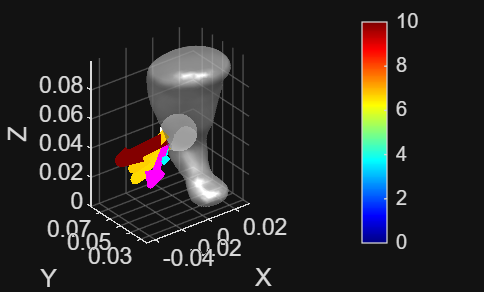

axis equal
colorbar;

xlabel('X'); ylabel('Y'); zlabel('Z');

heatmap of area (by disp)

% Load data
vertices = readtable('stl_vertices.csv');
faces = readtable('stl_faces.csv');
results_coarse = readtable('optimization_results_coarse_exposed.csv');

r_x = retractions.x;
r_y = retractions.y;
r_z = retractions.z;
r_dx = retractions.dx;
r_dy = retractions.dy;
r_dz = retractions.dz;
r_f = retractions.F;
is_expert = retractions.expert;

v_arr = [vertices.x, vertices.y, vertices.z];
f_arr = [faces.v1, faces.v2, faces.v3] + 1;

area = results_coarse.area_exposed;
stress = results_coarse.displacement;
x_fine = results_coarse.pos_x;
y_fine = results_coarse.pos_y;
z_fine = results_coarse.pos_z;

% Create interpolant to map stress to vertices
F = scatteredInterpolant(x_fine, y_fine, z_fine, stress, 'natural', 'none');
vertex_stress = F(v_arr(:,1), v_arr(:,2), v_arr(:,3));

% Plot STL with heatmap coloring
figure;
h = trisurf(f_arr, v_arr(:,1), v_arr(:,2), v_arr(:,3),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceAlpha',0.2)

h =   Patch with properties:

    FaceColor: [0.8000 0.8000 0.8000]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [3270×3 double]
     Vertices: [1637×3 double]

  Show all properties


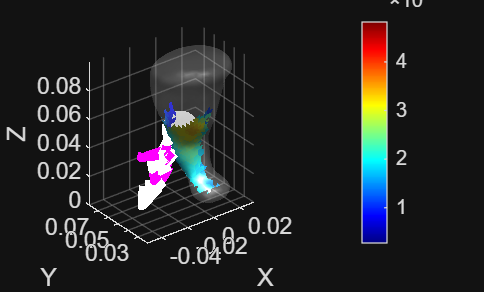

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'White'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'White'

color_str = 'White'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'White'

color_str = 'White'

color_str = 'White'

color_str = 'White'

color_str = 'White'

color_str = 'White'

hold on
exclude_radius = 0.01; 
dist_to_dissect = sqrt(sum((v_arr - dissect_pos).^2, 2));
vertex_stress(dist_to_dissect < exclude_radius) = NaN;
p = trisurf(f_arr, v_arr(:,1), v_arr(:,2), v_arr(:,3), ...
    vertex_stress, ...  % Color by interpolated stress
    'EdgeColor', 'none');

% Add colorbar and styling
colormap(jet);
colorbar;
clim([min(stress), max(stress)]);  % Match stress range
lighting gouraud;
camlight('left')
camlight('right')
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');

hold on;
scatter3(dissect_pos(1), dissect_pos(2), dissect_pos(3), ...
    200, 'white', 'filled');
for i = 1:length(r_x)
    if is_expert(i) == 1
        color_str = 'Magenta'
    else
        color_str = 'White'
    end

    quiver3(r_x(i), r_y(i), r_z(i), r_dx(i)*r_f(i), r_dy(i)*r_f(i), r_dz(i)*r_f(i), 0.01,'Color',color_str,'Linewidth',0.5*r_f(i),'MaxHeadSize',2)
end

heatmap of area

% Load data
vertices = readtable('stl_vertices.csv');
faces = readtable('stl_faces.csv');
% results_coarse = readtable('optimization_results_coarse_exposed.csv');
results_coarse = readtable('optimization_results/L1A2 SAD fine.csv')

results_coarse = 71×11 table
    Var1    retraction_ind       pos_x        pos_y       pos_z       dir_x       dir_y       dir_z      area_exposed    stress_induced    displacement
    ____    ______________    ___________    ________    ________    ________    ________    ________    ____________    ______________    ____________

     35          161            0.0045244    0.043049      0.0262    -0.17101    -0.96985     0.17365     1.6416e-05         6853.8          0.006049  
    103          169           0.00099874    0.045679    0.028988    -0.17101    -0.96985    -0.17365     1.5823e-05         7523.4         

r_x = retractions.x;
r_y = retractions.y;
r_z = retractions.z;
r_dx = retractions.dx;
r_dy = retractions.dy;
r_dz = retractions.dz;
r_f = retractions.F;
is_expert = retractions.expert;
r_id = retractions.id;

v_arr = [vertices.x, vertices.y, vertices.z];
f_arr = [faces.v1, faces.v2, faces.v3] + 1;

area_raw = results_coarse.area_exposed;
area = rescale(results_coarse.area_exposed, 0, 10);
stress_raw = results_coarse.stress_induced;
stress = rescale(results_coarse.stress_induced,0,10);
disp_raw = results_coarse.displacement

disp_raw =     0.0060
    0.0059
    0.0074
    0.0057
    0.0082
    0.0086
    0.0085
    0.0042
    0.0085
    0.0081
    0.0080
    0.0084
    0.0090
    0.0069
    0.0067


disp = rescale(results_coarse.displacement,0,10);
score = 0.7 * area + 0.2 * disp + 0.1 * stress

score =     2.3190
    1.7928
    4.5171
    1.5051
    6.2480
    6.6748
    6.8341
         0
    6.6056
    6.2688
    5.7457
    6.2955
    7.2081
    4.2645
    3.6428


x_c = results_coarse.pos_x;
y_c = results_coarse.pos_y;
z_c = results_coarse.pos_z;

% Create interpolant to map stress to vertices
F = scatteredInterpolant(x_c, y_c, z_c, stress_raw, 'natural', 'none');
vertex_stress = F(v_arr(:,1), v_arr(:,2), v_arr(:,3));

% Plot STL with heatmap coloring
figure;
h = trisurf(f_arr, v_arr(:,1), v_arr(:,2), v_arr(:,3),'FaceColor',[0.8 0.8 0.8],'EdgeColor','none','FaceAlpha',0.2)

h =   Patch with properties:

    FaceColor: [0.8000 0.8000 0.8000]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [3270×3 double]
     Vertices: [1637×3 double]

  Show all properties


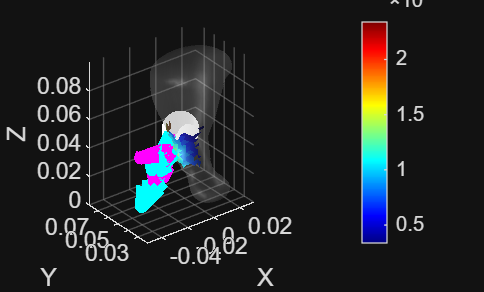

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'Cyan'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'Cyan'

color_str = 'Cyan'

color_str = 'Magenta'

color_str = 'Magenta'

color_str = 'Cyan'

color_str = 'Cyan'

color_str = 'Cyan'

color_str = 'Cyan'

color_str = 'Cyan'

color_str = 'Cyan'

hold on
exclude_radius = 0.01; 
dist_to_dissect = sqrt(sum((v_arr - dissect_pos).^2, 2));
vertex_stress(dist_to_dissect < exclude_radius) = NaN;
p = trisurf(f_arr, v_arr(:,1), v_arr(:,2), v_arr(:,3), ...
    vertex_stress, ...  % Color by interpolated stress
    'EdgeColor', 'none');

% Add colorbar and styling
colormap(jet);
colorbar;
clim([min(stress_raw), max(stress_raw)]);  % Match stress range
lighting gouraud;


light('Position',[-1.0 ,0.0 ,0.0]);

axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');

hold on;
scatter3(dissect_pos(1), dissect_pos(2), dissect_pos(3), ...
    200, 'white', 'filled');
for i = 1:length(r_x)
    if is_expert(i) == 1
        color_str = 'Magenta'
    else
        color_str = 'Cyan'
    end
   
    quiver3(r_x(i), r_y(i), r_z(i), r_dx(i)*r_f(i), r_dy(i)*r_f(i), r_dz(i)*r_f(i), 0.01,'Color',color_str,'Linewidth',0.8*r_f(i),'MaxHeadSize',3)
    
end